# Bifurcation diagram for a quantum graph on a periodic hexagonal grid

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

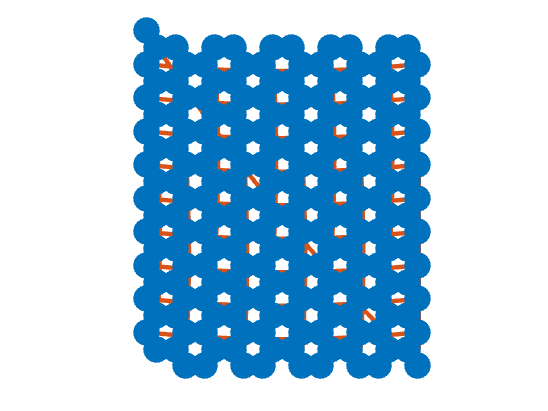

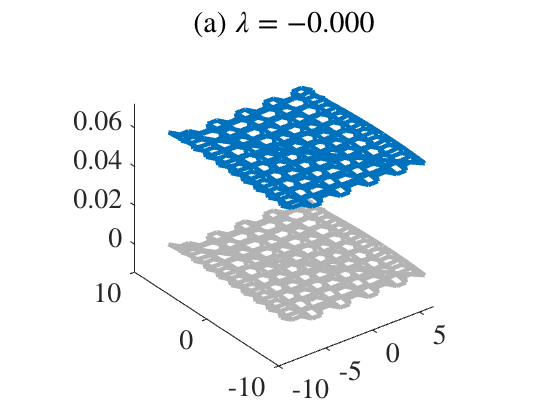

Saved to directory data/hex/012.
Run number is 12.


tag='hex';
[Phi,PhiX,extensionMap] =hexGridPeriodic(nx1=10,nx2=10,nx=20); % use the default values
nToPlot=1;
nDoubles=0;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

savePeriodicData(tag,diagramNumber,PhiX,extensionMap)

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

Lambda0=-4;
options=continuerSet([],'LambdaThresh',-4.1,'NThresh',10,'plotFlag',false,'maxTheta',2);


#### Compute a large-amplitude edge-centered solution, save it to a file, and compute its continuation

x0=[0 0];
filenumber=saveHighFrequencyStandingWaveGraphical(tag,diagramNumber,Lambda0,x0);
[bn1,bl1]=continueFromSaved(tag,diagramNumber,filenumber,-4,options);
bifurcationDiagram(tag,diagramNumber)

#### Compute a large-amplitude edge-centered solution, save it to a file, and compute its continuation

x0=[1/4, -sqrt(3)/4];
filenumber=saveHighFrequencyStandingWaveGraphical(tag,diagramNumber,Lambda0,x0);

File saved to data/hex/012/savedFunction.001.
File number is 1. 


[bn2,bl2]=continueFromSaved(tag,diagramNumber,filenumber,-4,options);
bifurcationDiagram(tag,diagramNumber)

#### Compute a large-amplitude edge-centered solution, save it to a file, and compute its continuation

x0=[3/4 sqrt(3)/4];
filenumber=saveHighFrequencyStandingWaveGraphical(tag,diagramNumber,Lambda0,x0);
options=continuerSet(options,'maxTheta',1.5,'NThresh',21.5,'minNormDelta',2e-3);ls
[bn3,bl3]=continueFromSaved(tag,diagramNumber,filenumber,-4,options);
bifurcationDiagram(tag,diagramNumber)

## Plot some solutions

plotSolution(tag,diagramNumber,bn1,1)

plotSolution(tag,diagramNumber,bn2,1)

plotSolution(tag,diagramNumber,bn3,1)